# Potential flow around an object

The partial differential equation for an inviscid flow is given by:

        
$$\frac{\partial \phi}{\partial t} = \nabla^2 \phi$$


The PDE can be solved numerically subject to different boundary conditions. These can be classified as:

**Dirichlet boundary conditions**


$$\phi = f(\mathbf{x},t)$$


**Neumann boundary conditions**


$$\frac{ \partial \phi}{\partial x} = f(\mathbf{x},t)$$


**Robin boundary conditions**


$$\phi + \frac{ \partial \phi}{\partial x} = f(\mathbf{x},t)$$


Remember that the boundary conditions you choose must satisfy the governing equations.

Today we will focus on potential flow solutions. To do so, we will use Matlab's PDE toolbox functions. Remember that the velocity vectors can be evaluated as:

 
$$\mathbf{u} = \frac{\partial \phi}{\partial \mathbf{x}}$$


## Solving the PDE

The workflow for a FE analysis is

#### Create model

model = createpde(1);

#### Create/import geometry

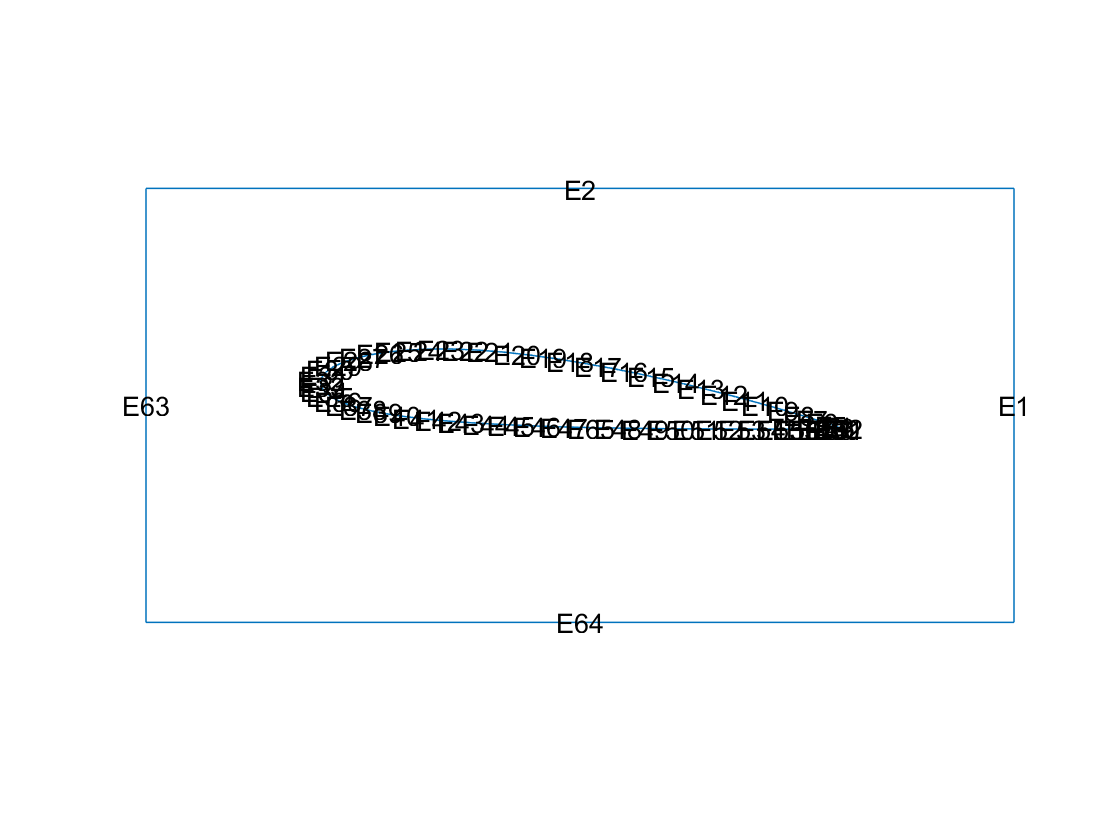

r1 = [3 4 -.5 .5 .5 -.5  -.25 -.25 .25 .25];         % row 1 gives shape (1,2,3,4) = circle, polygon, rectangle, ellipse
r2 = [3 4 -.2 .2 .2 -.2  -.2 -.2 .2 .2];
c2 = [1 0 0 0.2 0 0 0 0 0 0];                    % circle, x-centre, y-centre, radius, pad with zeros up to 10
e2 = [4 0 0 0.2 0.05 pi 0 0 0 0]      ;        % ellipse, x-centre, y-centre, major axis, minor axis, pad with zeros up to 10

NACA = NACA_profiles('A4016');
% pad domani with zeros wrt to the NACA profile
r1 = cat(2,r1,zeros(1,size(NACA,1)*2-8));

NACA(:,1) = NACA(:,1)-0.5;   % centre aerofoil on (0,0)
scale_factor = 0.6;          % linearly stretch
NACA = scale_factor*NACA;
theta = 5;
rot_Matrix = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
NACA = NACA*rot_Matrix;
aerofoil = [2, size(NACA,1), NACA(:,1)',NACA(:,2)'];

gdm = [r1; aerofoil]';

g = decsg(gdm,'Obj1-Obj2',['Obj1'; 'Obj2']');

geometryFromEdges(model,g);

figure
pdegplot(model,'EdgeLabels','on'); 
set(gca,'visible','off')

#### Choose governing equation and set boundary conditions & properties

There are functions to solve for generalised PDEs using finite elements. These are in the form:


$$m \frac{\partial^2 u}{\partial t^2} + d \frac{\partial u}{\partial t} - \nabla.(c\nabla u)+au=f$$


subject to:

**Dirichlet boundary conditions                                      **$hu=r$

**Generalised Neumann boundary conditions             **$\mathbf{n} .(c .\nabla u) + qu =g$

c = 1;
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0); 

applyBoundaryCondition(model,'neumann','edge',63,'g',-1);
applyBoundaryCondition(model,'neumann','edge',1,'g',1);
applyBoundaryCondition(model,'neumann','edge',2:62,'g',0);
applyBoundaryCondition(model,'neumann','edge',64,'g',0);

#### Generate mesh

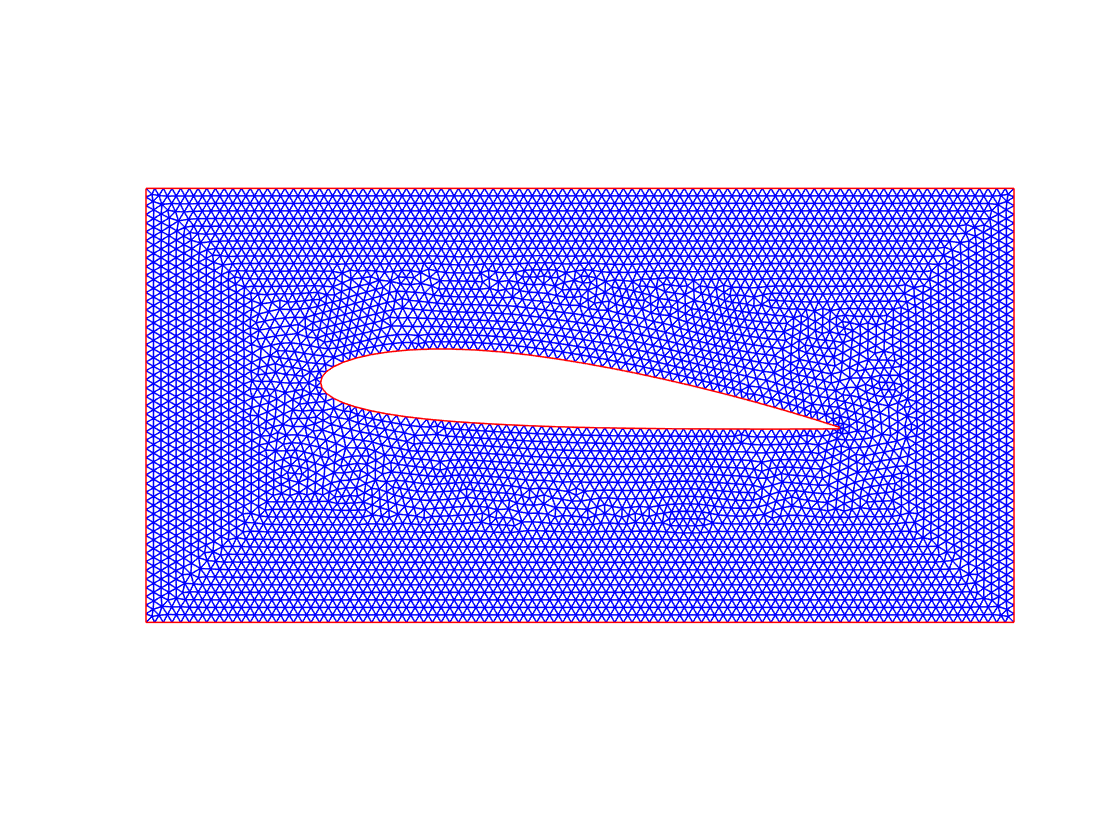

generateMesh(model,'Hmax',0.01);
figure 
pdeplot(model); 
axis equal
set(gca,'visible','off')

#### Solve equations 

R = solvepde(model);

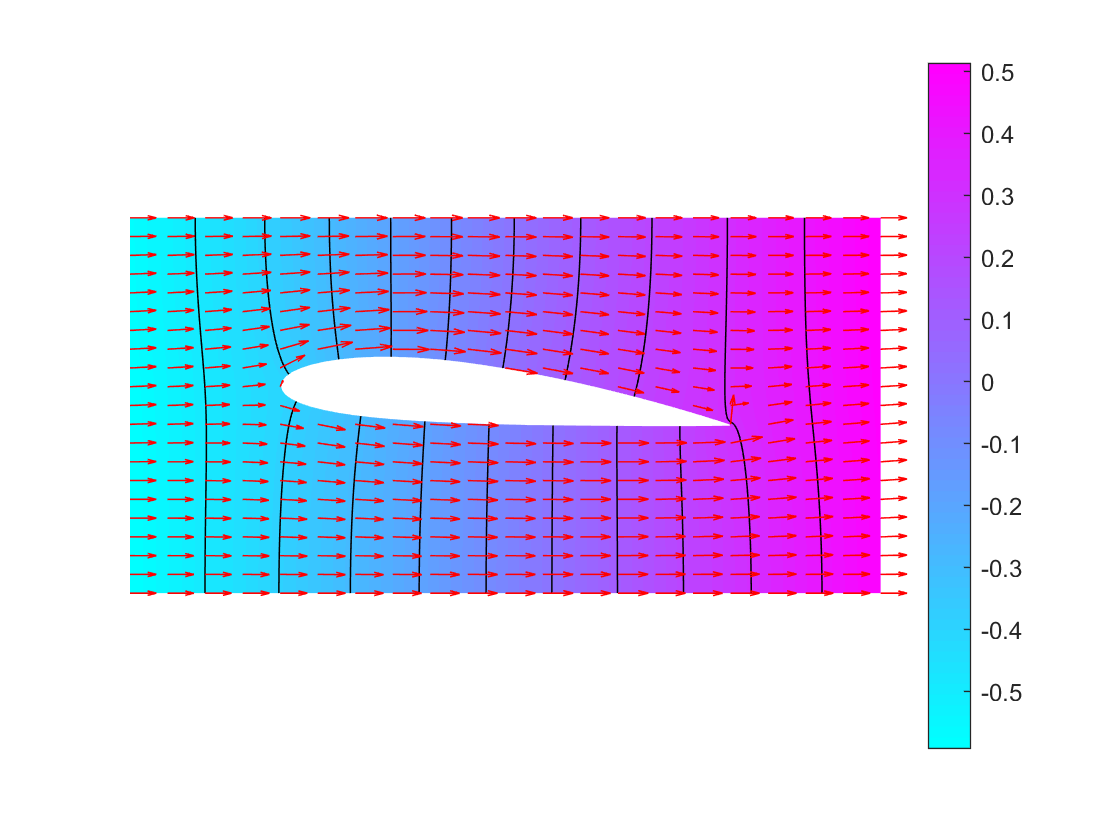

Phi = R.NodalSolution;
u = R.XGradients;
v = R.YGradients;

figure
pdeplot(model,'XYData',Phi,'Contour','on','FlowData',[u,v]); 
axis equal
set(gca,'visible','off')

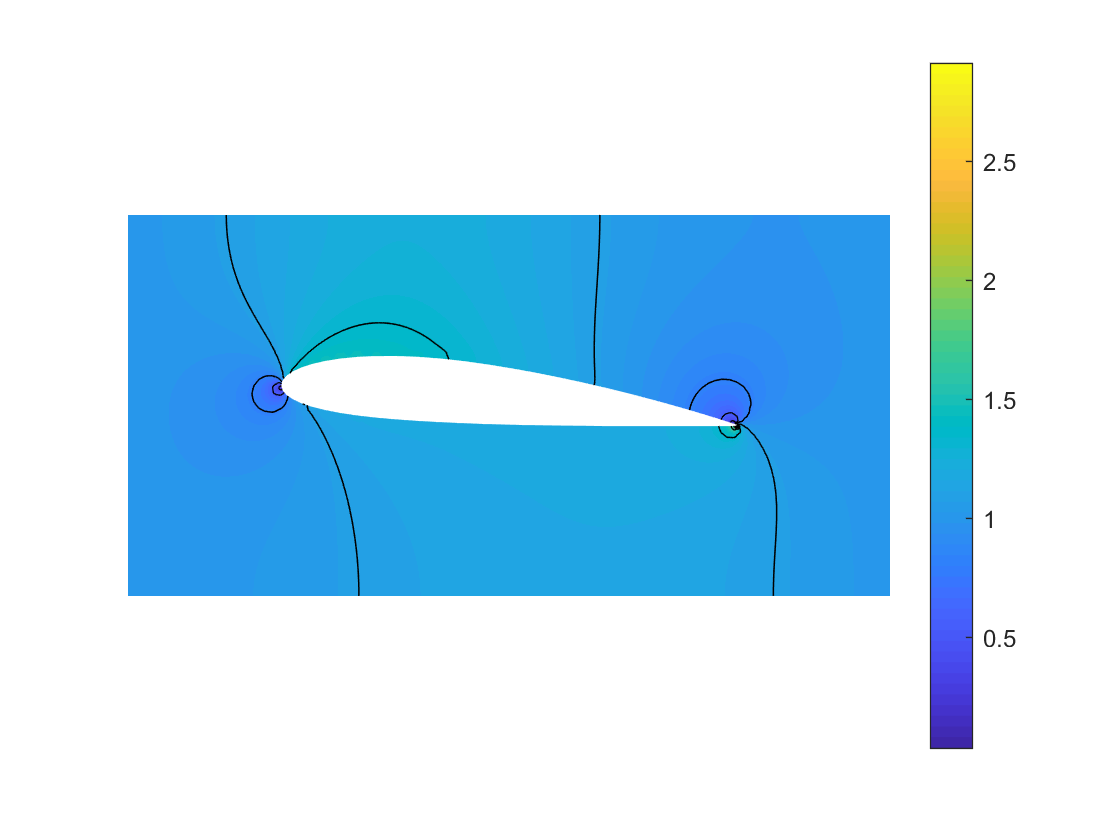

% velocity magnitude
figure
pdeplot(model,'XYData',sqrt(u.^2 + v.^2),'Contour','on','ColorMap','parula'); 
axis equal
set(gca,'visible','off')

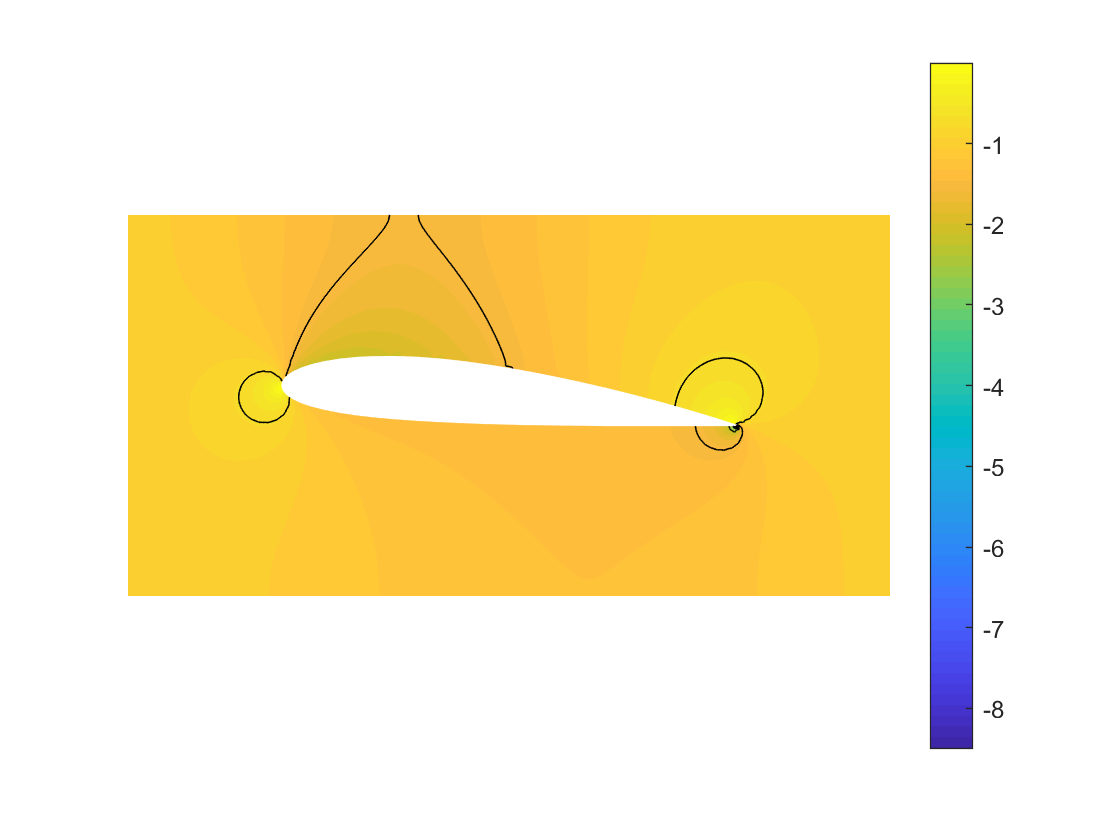

%% dynamic pressure field
figure
pdeplot(model,'XYData',- (u.^2 + v.^2),'Contour','on','ColorMap','parula'); 
axis equal
set(gca,'visible','off')

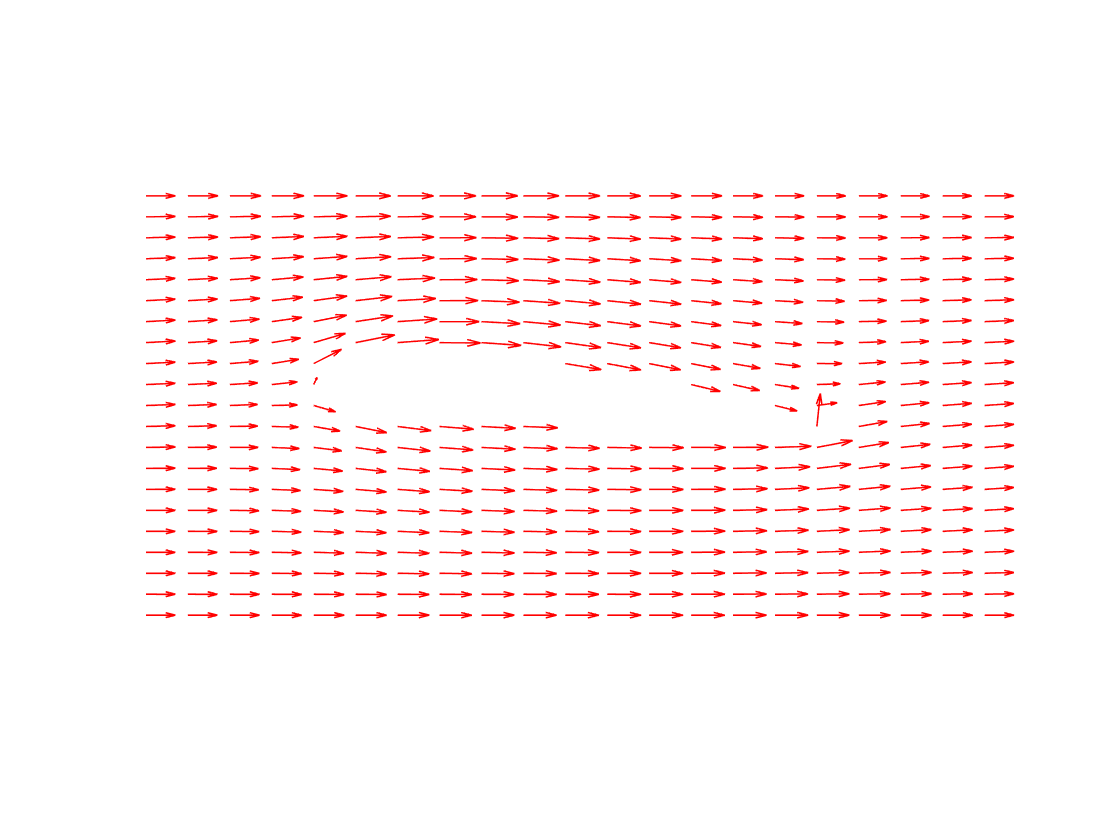

%% velocity vector field
nodes = model.Mesh.Nodes;
figure
pdeplot(model,'FlowData',[u, v]) 
axis equal
set(gca,'visible','off')

#### Interpolate nodes on a regular matrix grid

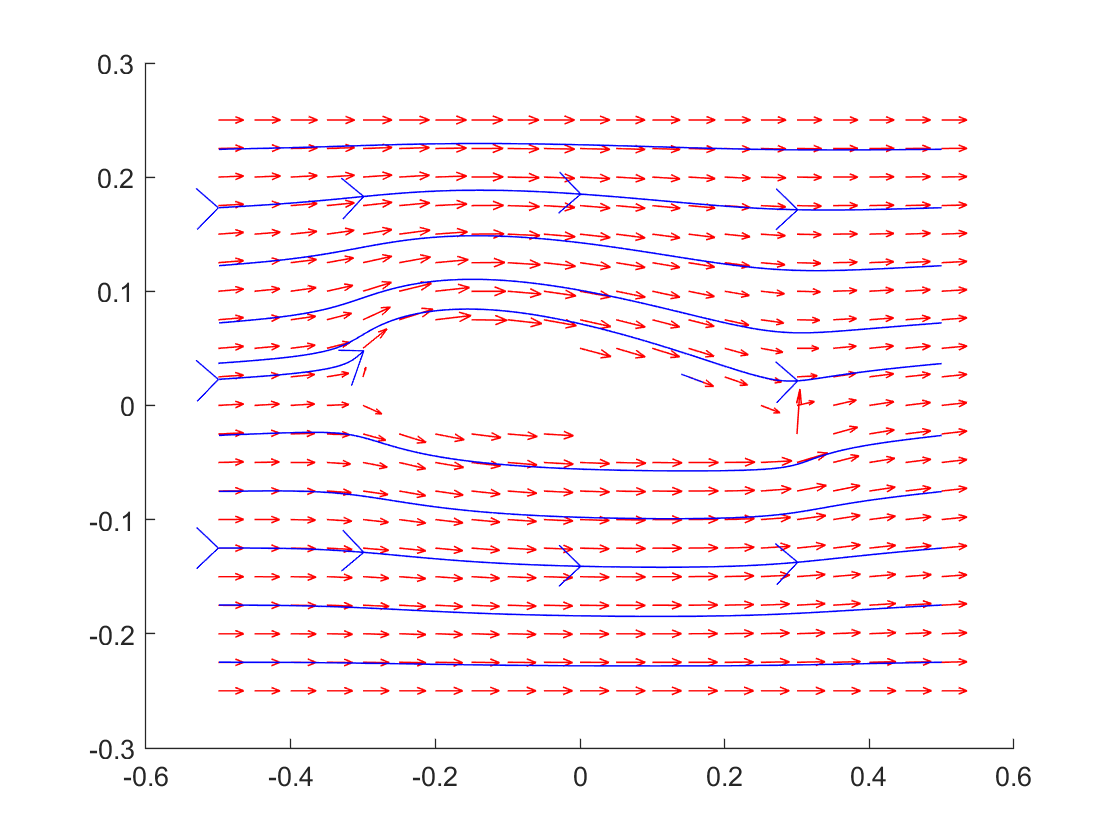

dx = 0.01;
[X,Y] = meshgrid(-1:dx:1,-0.5:dx:0.5);

Psi_interp = interpolateSolution(R,X,Y);
Psi_interp = reshape(Psi_interp,size(X));


[U, V] = evaluateGradient(R,X,Y);
U = reshape(U,size(X));
V = reshape(V,size(X));

figure('Color','w')
pdeplot(model,'FlowData',[u, v]) 
streamslice(X,Y,U,V)

function NACA = NACA_profiles(name)
if name == 'A4016'
    NACA = [
        1.00000  0.00147
        0.99739  0.00210
        0.98929  0.00396
        0.97587  0.00700
        0.95729  0.01112
        0.93372  0.01620
        0.90542  0.02207
        0.87267  0.02857
        0.83582  0.03552
        0.79527  0.04274
        0.75143  0.05004
        0.70480  0.05723
        0.65586  0.06412
        0.60515  0.07053
        0.55324  0.07629
        0.50069  0.08120
        0.44808  0.08512
        0.39598  0.08787
        0.34454  0.08913
        0.29482  0.08866
        0.24740  0.08645
        0.20285  0.08255
        0.16169  0.07707
        0.12440  0.07014
        0.09141  0.06198
        0.06310  0.05281
        0.03977  0.04289
        0.02165  0.03245
        0.00892  0.02171
        0.00169  0.01085
        0.00000  0.00000
        0.00379 -0.01031
        0.01293 -0.01956
        0.02730 -0.02770
        0.04669 -0.03471
        0.07087 -0.04054
        0.09957 -0.04516
        0.13246 -0.04858
        0.16918 -0.05082
        0.20937 -0.05195
        0.25260 -0.05208
        0.29844 -0.05133
        0.34644 -0.04987
        0.39611 -0.04787
        0.44739 -0.04537
        0.49931 -0.04232
        0.55129 -0.03886
        0.60276 -0.03516
        0.65316 -0.03132
        0.70194 -0.02745
        0.74857 -0.02365
        0.79252 -0.01998
        0.83331 -0.01650
        0.87048 -0.01328
        0.90360 -0.01035
        0.93230 -0.00776
        0.95626 -0.00557
        0.97518 -0.00381
        0.98886 -0.00252
        0.99713 -0.00173
        1.00000 -0.00147];
else
    NACA = [1 0; 0 0; 0 -0.2; 1 -0.2];
    disp('NACA profile not find - default rectangle imported')
end
end